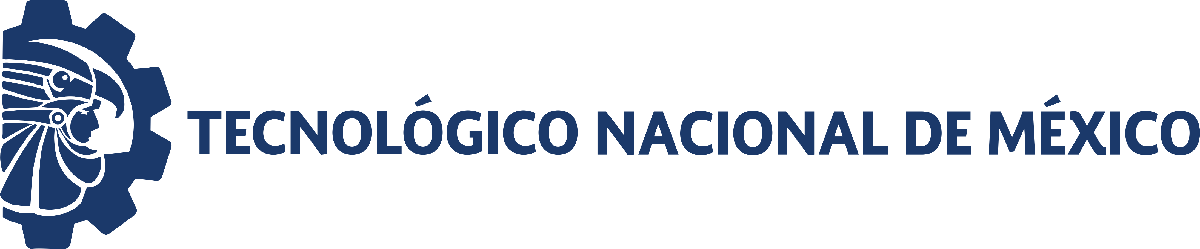                                 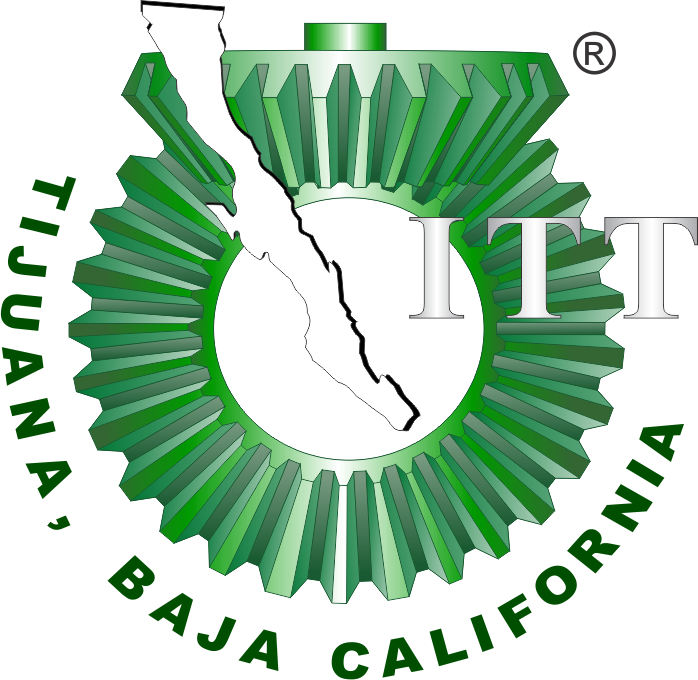

# Práctica Dos: Sistema Cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

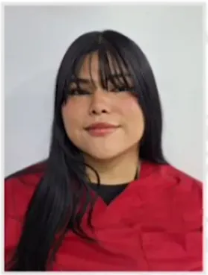

Nombre del alumno: **Paola Gonzalez Sanchez**

Número de control: **22211757**

Correo institucional: **L22211757@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = '10';
file = 'Sistema_3';
open_system(file);
parameters.StopTime = tend; 
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('Sistema_3/Pa(t)', 'Minimum', '-0.2');
set_param('Sistema_3/Pa(t)', 'Maximum', '1');
set_param('Sistema_3/Pa(t)', 'Seed', '106');
set_param('Sistema_3/Pa(t)', 'SampleTime', '0.5');
x = sim(file, parameters);
writematrix(x.Pa,'signal.xlsx')
plotsignals(x.t, x.Pp0, x.Pp1, x.Pp2, x.Pp3, x.Pp4);

set_param('Sistema_3/Pa(t)', 'Minimum', '-0.2');
set_param('Sistema_3/Pa(t)', 'Maximum', '1');
set_param('Sistema_3/Pa(t)', 'Seed', '106');
set_param('Sistema_3/Pa(t)', 'SampleTime', '0.5');
x1 = sim(file, parameters);
plotsignal(x1.t, x1.Pp0, x1.Pp1, x1.Pp2);

## Función: Respuesta a las señales

function plotsignals (t,Pp0,Pp1, Pp2,Pp3,Pp4)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                ]/255;
    colororder(mycolors);
    p = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-', t, Pp3, '--x', t,Pp4 ,'--d' ...
        ,'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Pp_{0}(t): Normotenso$','$Pp_{1}(t): Hipotenso$','$Pp_{2}(t): Hipertenso$', ...
        '$Pp_{3}(t): Hipotenso (PID)$','$Pp_{4}(t): Hipertenso (PID)$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    exportgraphics(gcf, 'Cardiovascular.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Cardiovascular.png', 'ContentType', 'vector')
end

function plotsignal(t,Pp0,Pp1,Pp2)
set(figure(), 'Color', 'w');
    set(gcf, 'units', 'centimeters', 'position', [1,1,18,8]);
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);
    hold on; grid off; box on; 
    mycolors = [011,029,081;
                114,094,173;
                140,205,235;
                223, 57, 105;
                127, 76, 165;
                5, 127, 109;
                ]/255;
    colororder(mycolors);
    p = plot(t, Pp0, '-', t, Pp1, '-', t, Pp2, '-',...
      'LineWidth', 1.5, 'MarkerSize', 5, 'MarkerIndices', 1:1000:length(t));
    set(p(1), 'LineWidth', 3);
    L = legend('$Pp_{0}(t)$','$Pp_{1}(t)$','$Pp_{2}(t)$');
    title(L,'Respuestas', 'FontSize', 10);
    set(L, 'Interpreter', 'Latex', 'FontSize', 10, 'Location', 'BestOutside', 'Box', 'On');
    xlabel('$t$ $[s]$', 'Interpreter', 'Latex', 'FontSize', 11);
    ylabel('$Pp_i(t)$ $[v]$', 'Interpreter', 'Latex', 'FontSize', 11);
    xlim([0, 10]); xticks(0:1:10); 
    exportgraphics(gcf, 'Cardiovascular1.pdf', 'ContentType', 'vector')
    exportgraphics(gcf, 'Cardiovascular1.png', 'ContentType', 'vector')
end

